# Chemical Reactor

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

The concentration over time of a chemical in a reactor is given by the differential equation:

*d**C/d**t*=2*t*−1/2 *t^*2

In the partially completed script `chemReactor.mlx`, this ODE has been implemented in the local function `reactor`.

In this interaction, you will complete the script to determine the chemical concentration from *t*=0 to *t*=4, with an initial concentration *C*(0)=0.

1.  Define the time interval.

tRange = [0 4];

2.  Define the initial condition.

C0 = 0;

3.  Call the `ode45` function to solve the ODE.

[tSol, CSol] = ode45(@reactor, tRange, C0)

tSol =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


CSol =          0
    0.0098
    0.0387
    0.0855
    0.1493
    0.2292
    0.3240
    0.4328
    0.5547
    0.6885


4.  Plot the solution.

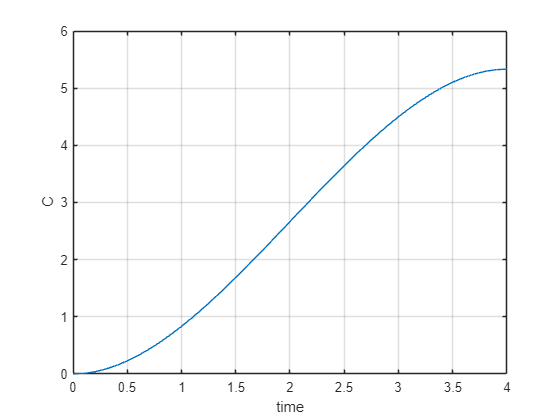

plot(tSol, CSol)
grid on

% Annotate the plot
xlabel("time")
ylabel("C")

Do not edit. This code defines the ODE function to solve the ODE  .

function dCdt = reactor(t, C)
    % Define dCdt:
    dCdt = 2*t - 1/2*t.^2;
end